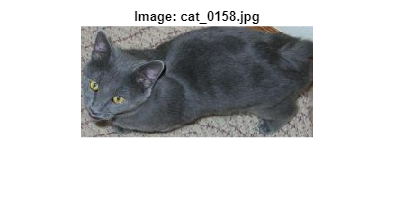

% 1.READ THE IMAGE FOLDER.
folderPath = 'cat';


fileList = dir(folderPath);

% Loop through each file in the folder
for i = 1:length(fileList)
    
    if ~fileList(i).isdir
        
        filePath = fullfile(folderPath, fileList(i).name);
        
        % Read the image using imread
        image = imread(filePath);
        
        
        imshow(image);
        title(['Image: ' fileList(i).name], 'Interpreter', 'none');
        pause(1);  % Pause for some time to view each image (optional)
    end
end

% 2.RESIZE ALL IMAGES WITH 126*126 RESOLUTION


folderPath = 'cat';


fileList = dir(folderPath);

% Loop through each file in the folder
for i = 1:length(fileList)
    % Check if the item is a file 
    if ~fileList(i).isdir
        
        filePath = fullfile(folderPath, fileList(i).name);
        
        
        originalImage = imread(filePath);
        
        % Resize the image to 126x126
        resizedImage = imresize(originalImage, [126, 126]);
        
        % Display the original and resized images 
        subplot(1, 2, 1);
        imshow(originalImage);
        title(['Original Image: ' fileList(i).name], 'Interpreter', 'none');
        
        subplot(1, 2, 2);
        imshow(resizedImage);
        title(['Resized Image: ' fileList(i).name], 'Interpreter', 'none');
        
        pause(1);  
    end
end

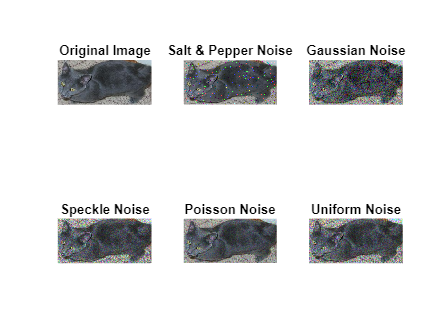

% 3. Apply noises and remove noises by applying image filters (apply at least 5 filters for comparison)

originalImage = imread('cat_0158.jpg');

% Display the original image
figure;
subplot(2, 3, 1);
imshow(originalImage);
title('Original Image');

% Apply different types of noises
noisyImage_salt_and_pepper = imnoise(originalImage, 'salt & pepper', 0.02);
noisyImage_gaussian = imnoise(originalImage, 'gaussian', 0, 0.01);
noisyImage_speckle = imnoise(originalImage, 'speckle', 0.04);
noisyImage_poisson = imnoise(originalImage, 'poisson');
noisyImage_uniform = imnoise(originalImage, 'speckle', 0.04);

% Display the noisy images
subplot(2, 3, 2);
imshow(noisyImage_salt_and_pepper);
title('Salt & Pepper Noise');

subplot(2, 3, 3);
imshow(noisyImage_gaussian);
title('Gaussian Noise');

subplot(2, 3, 4);
imshow(noisyImage_speckle);
title('Speckle Noise');

subplot(2, 3, 5);
imshow(noisyImage_poisson);
title('Poisson Noise');

subplot(2, 3, 6);
imshow(noisyImage_uniform);
title('Uniform Noise');


% Apply different filters to remove noise
filteredImage_median = medfilt2(noisyImage_salt_and_pepper);
filteredImage_gaussian = imgaussfilt(noisyImage_gaussian, 2);
filteredImage_wiener = wiener2(noisyImage_speckle, [5, 5]);
filteredImage_adaptive_median = admedian(noisyImage_poisson, 5);
filteredImage_average = filter2(fspecial('average', [3, 3]), noisyImage_uniform);

% Display the filtered images
figure;
subplot(2, 3, 1);
imshow(filteredImage_median);
title('Median Filter');

subplot(2, 3, 2);
imshow(filteredImage_gaussian);
title('Gaussian Filter');

subplot(2, 3, 3);
imshow(filteredImage_wiener);
title('Wiener Filter');

subplot(2, 3, 4);
imshow(filteredImage_adaptive_median);
title('Adaptive Median Filter');

subplot(2, 3, 5);
imshow(filteredImage_average);
title('Average Filter');

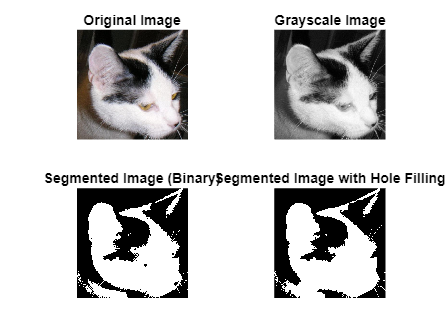

% 4. FURTHER DO THE SEGMENTATION TECHNIQUES.

originalImage = imread('cat_0151.jpg');

% Display the original image
figure;
subplot(2, 2, 1);
imshow(originalImage);
title('Original Image');

% Convert the image to grayscale if it is in RGB 
if size(originalImage, 3) == 3
    grayImage = rgb2gray(originalImage);
else
    grayImage = originalImage;
end

% Display the grayscale image
subplot(2, 2, 2);
imshow(grayImage);
title('Grayscale Image');

level = graythresh(grayImage);
binaryImage = imbinarize(grayImage, level);

% Display the binary segmented image
subplot(2, 2, 3);
imshow(binaryImage);
title('Segmented Image (Binary)');

filledImage = imfill(binaryImage, 'holes');

% Display the filled segmented image
subplot(2, 2, 4);
imshow(filledImage);
title('Segmented Image with Hole Filling');

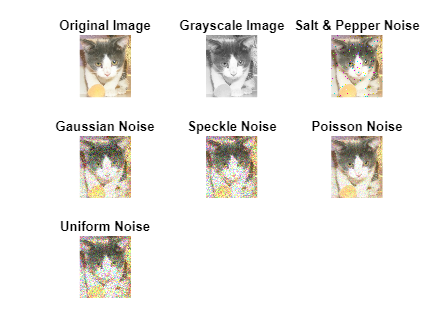

% 5. Display the image (9 images) after applying above activities using subplot function.


originalImage = imread('cat_0090.jpg');


figure;
subplot(3, 3, 1);
imshow(originalImage);
title('Original Image');

% Convert the image to grayscale 
if size(originalImage, 3) == 3
    grayImage = rgb2gray(originalImage);
else
    grayImage = originalImage;
end

subplot(3, 3, 2);
imshow(grayImage);
title('Grayscale Image');

% Apply different types of noises
noisyImage_salt_and_pepper = imnoise(originalImage, 'salt & pepper', 0.02);
noisyImage_gaussian = imnoise(originalImage, 'gaussian', 0, 0.01);
noisyImage_speckle = imnoise(originalImage, 'speckle', 0.04);
noisyImage_poisson = imnoise(originalImage, 'poisson');
noisyImage_uniform = imnoise(originalImage, 'speckle', 0.04);

% Display the noisy images
subplot(3, 3, 3);
imshow(noisyImage_salt_and_pepper);
title('Salt & Pepper Noise');

subplot(3, 3, 4);
imshow(noisyImage_gaussian);
title('Gaussian Noise');

subplot(3, 3, 5);
imshow(noisyImage_speckle);
title('Speckle Noise');

subplot(3, 3, 6);
imshow(noisyImage_poisson);
title('Poisson Noise');

subplot(3, 3, 7);
imshow(noisyImage_uniform);
title('Uniform Noise');


% Apply different filters to remove noise
filteredImage_median = medfilt2(noisyImage_salt_and_pepper);
filteredImage_gaussian = imgaussfilt(noisyImage_gaussian, 2);
filteredImage_wiener = wiener2(noisyImage_speckle, [5, 5]);
filteredImage_adaptive_median = admedian(noisyImage_poisson, 5);
filteredImage_average = filter2(fspecial('average', [3, 3]), noisyImage_uniform);

% Display the filtered images
subplot(3, 3, 8);
imshow(filteredImage_median);
title('Median Filter');

subplot(3, 3, 9);
imshow(filteredImage_gaussian);
title('Gaussian Filter');


level = graythresh(grayImage);
binaryImage = imbinarize(grayImage, level);


figure;
subplot(1, 2, 1);
imshow(binaryImage);
title('Segmented Image (Binary)');


filledImage = imfill(binaryImage, 'holes');


subplot(1, 2, 2);
imshow(filledImage);
title('Segmented Image with Hole Filling');
